# Paper3: 1st test

How will a 4*8 binocular patch work?

## Setting up WS

CurrentFolder = pwd

CurrentFolder = '/Users/zhuochengxiao/Library/CloudStorage/OneDrive-Personal/Documents/GitHub/NYU-Vision-2Drive'

addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
DataFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/Paper3PlotingData/']; % V1D2
DataFolder1 = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/GlobConv/']; % V1D2
DataFolder2 = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/Paper2PlotingData/Typical_trajs/']; % V1D2
DataFolder3 = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/Paper2PlotingData/']; % V1D2
SaveToFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/Paper3TestingKernelData/']; % V1D2

addpath(DataFolder3)
addpath(DataFolder2)
addpath(DataFolder1)
addpath(DataFolder)
addpath([CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/'])

FigurePaperPath = [CurrentFolder '/Figures/Demo052023/']; % V1D2

### B1. Load LDE computations and do Fr distributions

Should rerun Sect 1 after in case loaded file contain any paths.

DataPoint = 'V4D2'; %'V4D1'; 'V5D1'
load(sprintf("AllMFPixPara_Paper2TuneFig1%s.mat",DataPoint))

CurrentFolder = pwd;
FigurePaperPath = [CurrentFolder '/Figures/Demo052023/']; % V1D2
close all

## 2. Set up LDE firing rate functions

first get basic function information

%AngleList = {'0.0'}; % only vertical for now
AngleList = {'0.0','7.5','15.0','22.5'};
DomList =  {'Small','Large','LARGER'};

## 3. Set up initial conditions

N_HCOutX = 4; N_HCOutY = 8; PixNumOut = N_HCOutX*N_HCOutY*NPixX*NPixY;
N_HCinX = 4; N_HCinY = 4;
NPixX = 10; NPixY = 10;

Parameters of L4 kernels

MonocuFlag = false;
AngleTestAll = 0:7.5:180; % 0:7.5:22.5; % has to be multiples of 7.5
TestNum = length(AngleTestAll);
TestExSeq = ones(size(0:7.5:180)); TestEySeq = zeros(size(TestExSeq)); 

Background

% LDEbgIC.S = 2.5*ones(N_HCOutX*NPixX*N_HCOutY*NPixY,1);
% LDEbgIC.C = 8*ones(N_HCOutX*NPixX*N_HCOutY*NPixY,1);
% LDEbgIC.I = 18*ones(N_HCOutX*NPixX*N_HCOutY*NPixY,1); %16
% LDEICOut = LDEbgIC;

%%%60 deg: by rotating 15 deg pattern

Start from 90, then go to 22.5

ICData = load([DataFolder2 sprintf('LDETracesV4D2_NewSmear_ang0.0.mat')]);
load('LDETracesV4D2_NewSmear_ang0.0.mat')
LDEICPart = ICData.LDEEquv;

LDEICOut = HCRotXY(LDEICPart,0,N_HCinX,N_HCinY,N_HCOutX,N_HCOutY,NPixX,NPixY,0);
for TestId = 1:TestNum
    ICTestAll{TestId} = LDEICOut;
end
LDEOutAll = cell(size(ICTestAll));
NANFlag = false(size(ICTestAll));
%BGFlagAllTest = cell(size(ICTestAll));

load equiv

%PlotUse = load([DataFolder2 sprintf('LDETraces_bg-ang%s.mat',AngPrint)],'LDEEquv');
%LDEEquv = PlotUse.LDEEquv;
%LDEEquv = HCRot(LDEEquv,RotInd,N_HCOut,NPixX,NPixY,MirInd);

Hyperparameters of iterations

p = 0.33;% 1-p for the original input
EpocTest = 50;
ExportFlag = 'xn';

L2Diff_OneStepAll = zeros(length(ICTestAll),EpocTest+1);
DiffVecAll = zeros(length(ICTestAll),EpocTest+1,3*NPixY*NPixX);

Since we are doing different network architectures now - need to separate inputs to the S C I functions!!!

% Determine L4 Input from a range
L4SE = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4SI = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4CE = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4CI = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4IE = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4II = zeros(N_HC*NPixX*N_HC*NPixY,1);
for PInd = 1:N_HC*NPixX*N_HC*NPixY
L4SE(PInd) = (C_SS_Pixel_Us(PInd,:)*FrSPixVec          + C_SC_Pixel_Us(PInd,:)*FrCPixVec);
L4SI(PInd) =  C_SI_Pixel_Us(PInd,:)*FrIPixVec ;
L4CE(PInd) = (C_CS_Pixel_Us(PInd,:)*FrSPixVec          + C_CC_Pixel_Us(PInd,:)*FrCPixVec);
L4CI(PInd) =  C_CI_Pixel_Us(PInd,:)*FrIPixVec ;
L4IE(PInd) = (C_IS_Pixel_Us(PInd,:)*FrSPixVec          + C_IC_Pixel_Us(PInd,:)*FrCPixVec);
L4II(PInd) =  C_II_Pixel_Us(PInd,:)*FrIPixVec ;
end
L4Eall = L4SE+L4CE+L4IE; L4Iall = L4SI+L4CI+L4II;
L4SEp = mean(L4SE./L4Eall);L4CEp = mean(L4CE./L4Eall);L4IEp = mean(L4IE./L4Eall);
L4SIp = mean(L4SI./L4Iall);L4CIp = mean(L4CI./L4Iall);L4IIp = mean(L4II./L4Iall);

## 6*6 tests

We start from 1. BG for both eyes, and 2. Vertical for both eyes. Target: BG for left and vertical for right

for TestId = 1:TestNum
    AngleInpt = AngleTestAll(TestId)
    
    RotInd = floor(AngleInpt/45); % 0-3
    MirInd = mod(floor(AngleInpt/22.5),2); % 0: no mirror; 1: mirror
    switch MirInd % find the corresponding source
        case 0
            AngSource = mod(AngleInpt,45);
        case 1
            AngSource = mod(-AngleInpt,45);
    end
    
    % Use the source, decide which response function for angle should I use
    AngFuncCtgrCdid = 0:7.5:22.5;
    [~,AngFuncCtgr] = min(abs(AngFuncCtgrCdid - AngSource));
    
    AngPrint = AngleList{AngFuncCtgr};
    Angle = str2num(AngPrint); % can select from 0 7.5 15 22.5

load all precomputed domains

    L4EmeshXAll = cell(size(DomList));
    L4ImeshYAll = cell(size(DomList));
    LDEFrfuncAll = cell(size(DomList));
    for DomInd = 1:length(DomList)
        FuncTemp = load(sprintf('Func25%sAng%s%s.mat',DataPoint,AngPrint,DomList{DomInd}),...
            'LDEFrfunc','L4EmeshX','L4ImeshY');
        L4EmeshXAll{DomInd} = FuncTemp.L4EmeshX;
        L4ImeshYAll{DomInd} = FuncTemp.L4ImeshY;
        LDEFrfuncAll{DomInd} = FuncTemp.LDEFrfunc;
    end
    %% the finest BG function as well
    FuncTemp_BG = load('FuncBG_Smaller_SM15_5.mat','LDEFrfunc','L4EmeshX','L4ImeshY');
    L4EmeshXBG = FuncTemp_BG.L4EmeshX;
    L4ImeshYBG = FuncTemp_BG.L4ImeshY;
    LDEFrfuncBG = FuncTemp_BG.LDEFrfunc;

## 4. Iteration 

New: Need to extend all these to arbitrary HC numbers!

%    N_HCOut = 4; PixNumOut = N_HCOut^2*NPixX*NPixY;
    LGNlist = 5; L6list = 5;
    OD_SMapModi = OD_SMap;

Needs to replace the midel row as "5" -- Background

    %OD_SMapModi = OD_SMap(1:2*n_S_HC,1:2*n_S_HC);
    if MonocuFlag
        OD_SMapModi(n_S_HC+1:2*n_S_HC,1:end) = 5;  
        SaveStr = 'Monocu';
    else
        SaveStr = 'Binocu';
    end

LGN and L6 are blurred 

    N_HCs = 3; % shrink to 2*2
    FigOn = false;
    L6smear = n_S_HC*0.25; LGNsmear = n_S_HC*0.2;
    TruncL6 = 0.33/(L6smear/n_S_HC); TruncLGN = 1;
    L6SFilt_Grating = SpatialGaussianFilt_my(OD_SMapModi,...
        N_HCs,n_S_HC,L6smear,TruncL6,FigOn);
    LGNFilt_Grating = SpatialGaussianFilt_my(OD_SMapModi,...
        N_HCs,n_S_HC,LGNsmear,TruncLGN,FigOn);
    
    if ~MonocuFlag
        L6SFilt_Grating = [L6SFilt_Grating,zeros(size(L6SFilt_Grating,1),1)];
        LGNFilt_Grating = [LGNFilt_Grating,zeros(size(LGNFilt_Grating,1),1)];
    end

    PixL6Ctgr = LGNIndSpat_Rec(...
        L6SFilt_Grating,1:L6list,NnSPixel,N_HC,N_HCOutX,N_HCOutY,NPixX,NPixY,false);
    PixLGNCtgr = LGNIndSpat_Rec(...
        LGNFilt_Grating,1:LGNlist,NnSPixel,N_HC,N_HCOutX,N_HCOutY,NPixX,NPixY,true);

    % symmetrize !! This is actually tricky, so I do it ad hoc
    PixL6Ctgr = Ocu_LGNL6symm(PixL6Ctgr,N_HCOutX,N_HCOutY,NPixX,NPixY);
    PixLGNCtgr = Ocu_LGNL6symm(PixLGNCtgr,N_HCOutX,N_HCOutY,NPixX,NPixY);

completely BG or not?

    BGFlag = false;
    if BGFlag
        PixL6Ctgr(:,end) = 1; PixL6Ctgr(:,1:end-1) = 0; 
        PixLGNCtgr(:,end) = 1; PixLGNCtgr(:,1:end-1) = 0; 
    end

However, the Ctgr for pixels needs to be rotated/flipped to represent the actual gratings

**Instead of rotating existing ctgr fields, I should simply permute 1234  **

    MirInd = logical(MirInd);
    CtgrOrder = [2,1;3,4]; % for lower left HC
    CtgrOrderUse = rot90(CtgrOrder,RotInd);
    if MirInd
        %flipDim = mod(RotInd,2)+1; %1 for col 2 ofr row
        CtgrOrderUse = flip(CtgrOrderUse,1);
    end
    CtgrOrderReadout = ...
        [CtgrOrderUse(1,2);
        CtgrOrderUse(1,1);
        CtgrOrderUse(2,1);
        CtgrOrderUse(2,2)];
%    for Ctgr = 1:4
%         PixL6Ctgr(:,Ctgr) = ...
%             HCRot_Rec(PixL6Ctgr(:,Ctgr),RotInd,N_HCOutX,N_HCOutY,NPixX,NPixY,MirInd);
%         PixLGNCtgr(:,Ctgr) = ...
%             HCRot_Rec(PixLGNCtgr(:,Ctgr),RotInd,N_HCOutX,N_HCOutY,NPixX,NPixY,MirInd);  
%    end

    % let's implement something cheap now for 45 deg
    PixL6Ctgr = PixL6Ctgr(:,[CtgrOrderReadout',5]);
    PixLGNCtgr = PixLGNCtgr(:,[CtgrOrderReadout',5]);
    
    PixInptCtgrUse  = zeros(PixNumOut,LGNlist,L6list);
    for PixInd = 1:PixNumOut
        PixInptCtgrUse(PixInd,:,:) = PixLGNCtgr(PixInd,:)' *PixL6Ctgr(PixInd,:);% by multiplying both indexes
    end

Get pixelwise connectivities

NOTE: NEED to modify AveSpatKer_Rec to implement the ocular modulation of connectivity kernels    

    ParaEx = TestExSeq(TestId); ParaEy = TestEySeq(TestId);
    ParaIx = ParaEx;   ParaIy = ParaEy;

    C_SS_mean = sparse(AveSpatKer_Rec(C_SS_Pixel_Us,N_HC,...
        N_HCOutX,N_HCOutY,NPixX,NPixY,ParaEx,ParaEy));
    C_CS_mean = sparse(AveSpatKer_Rec(C_CS_Pixel_Us,N_HC,...
        N_HCOutX,N_HCOutY,NPixX,NPixY,ParaEx,ParaEy));
    C_IS_mean = sparse(AveSpatKer_Rec(C_IS_Pixel_Us,N_HC,...
        N_HCOutX,N_HCOutY,NPixX,NPixY,ParaEx,ParaEy));
    C_SC_mean = sparse(AveSpatKer_Rec(C_SC_Pixel_Us,N_HC,...
        N_HCOutX,N_HCOutY,NPixX,NPixY,ParaEx,ParaEy));
    C_CC_mean = sparse(AveSpatKer_Rec(C_CC_Pixel_Us,N_HC,...
        N_HCOutX,N_HCOutY,NPixX,NPixY,ParaEx,ParaEy));
    C_IC_mean = sparse(AveSpatKer_Rec(C_IC_Pixel_Us,N_HC,...
        N_HCOutX,N_HCOutY,NPixX,NPixY,ParaEx,ParaEy));
    C_SI_mean = sparse(AveSpatKer_Rec(C_SI_Pixel_Us,N_HC,...
        N_HCOutX,N_HCOutY,NPixX,NPixY,ParaIx,ParaIy));
    C_CI_mean = sparse(AveSpatKer_Rec(C_CI_Pixel_Us,N_HC,...
        N_HCOutX,N_HCOutY,NPixX,NPixY,ParaIx,ParaIy));
    C_II_mean = sparse(AveSpatKer_Rec(C_II_Pixel_Us,N_HC,...
        N_HCOutX,N_HCOutY,NPixX,NPixY,ParaIx,ParaIy));

    Conn_Reduc_Test = 5;
    Reduc_S = Conn_Reduc_Test*(1-CplxR); Reduc_C = Conn_Reduc_Test*CplxR;
    P_SS_rate = (N_SS-Reduc_S)/N_SS; C_SS_meanU = C_SS_mean * P_SS_rate;
    P_SC_rate = (N_SC-Reduc_C)/N_SC; C_SC_meanU = C_SC_mean * P_SC_rate;
    P_CS_rate = (N_CS-Reduc_S)/N_CS; C_CS_meanU = C_CS_mean * P_CS_rate;
    P_CC_rate = (N_CC-Reduc_C)/N_CC; C_CC_meanU = C_CC_mean * P_CC_rate;

Firing rate suppresion

    %     EKp.Thrsld = 50; EKp.Highist = [200,150]; EKp.HardBound = 200; EKp.Slope = 0;
    %
    %     IKp.Thrsld = 70; IKp.Highist = [100,95];  IKp.HardBound = 120; IKp.Slope = 1; % 1; 0.9(95); 0.8(9)

set up IC

    tic
    ICUse = ICTestAll{TestId}; % 
    IniTest = ICUse;
    %IniTest.S = symmHCs(ICUse.S,N_HCOut,NPixX,NPixY);
    %IniTest.C = symmHCs(ICUse.C,N_HCOut,NPixX,NPixY);
    %IniTest.I = symmHCs(ICUse.I,N_HCOut,NPixX,NPixY);
    

start iteration

    [LDEOutAll{TestId},~,~,~,~,FuncUse,...
        NANFlag(TestId)] = ...
        LDEIteration_25FuncMain_CombDom_BG(...
        PixInptCtgrUse,IniTest,p,EpocTest,...
        C_SS_meanU,C_CS_meanU,C_IS_mean,...
        C_SC_meanU,C_CC_meanU,C_IC_mean,...
        C_SI_mean, C_CI_mean, C_II_mean,...
        L4SEp, L4SIp, ...
        L4CEp, L4CIp, ...
        L4IEp, L4IIp, ...
        L4EmeshXAll,L4ImeshYAll,LDEFrfuncAll,...
        L4EmeshXBG, L4ImeshYBG, LDEFrfuncBG, ...
        N_HCOutY,NPixX,NPixY,false,'xn')  ;
    LDEEquv = LDEOutAll{TestId}{end};
    
    RunTime = toc;
    sprintf('RunTime = %.2f',RunTime)

    if ~NANFlag(TestId)
    for EpcInd = 1:EpocTest+1
        LDEPertRslt = LDEOutAll{TestId}{EpcInd};
        SDiff = LDEPertRslt.S - LDEEquv.S;
        SDiffHC = reshape(SDiff,N_HCOutY*NPixY,N_HCOutX*NPixX);
        SDiff = reshape(SDiffHC(1:NPixY,1:NPixX),NPixY*NPixX,1);
        CDiff = LDEPertRslt.C - LDEEquv.C;
        CDiffHC = reshape(CDiff,N_HCOutY*NPixY,N_HCOutX*NPixX);
        CDiff = reshape(CDiffHC(1:NPixY,1:NPixX),NPixY*NPixX,1);
        IDiff = LDEPertRslt.I - LDEEquv.I;
        IDiffHC = reshape(IDiff,N_HCOutY*NPixY,N_HCOutX*NPixX);
        IDiff = reshape(IDiffHC(1:NPixY,1:NPixX),NPixY*NPixX,1);
        
        L2Diff_OneStepAll(TestId,EpcInd) = ...
            sqrt(sum((SDiff*(1-CplxR)+CDiff*CplxR).^2,'all'));%sqrt(sum([SDiff;CDiff;IDiff].^2));
        DiffVecAll(TestId,EpcInd,:) = [SDiff;CDiff;IDiff];
    end
    end
end

AngleInpt = 0

Showing xn


ans = 'RunTime = 2.74'

AngleInpt = 7.5000

Showing xn


ans = 'RunTime = 2.71'

AngleInpt = 15

Showing xn


ans = 'RunTime = 2.71'

AngleInpt = 22.5000

Showing xn


ans = 'RunTime = 2.71'

AngleInpt = 30

Showing xn


ans = 'RunTime = 2.71'

AngleInpt = 37.5000

Showing xn


ans = 'RunTime = 2.72'

AngleInpt = 45

Showing xn


ans = 'RunTime = 2.67'

AngleInpt = 52.5000

Showing xn


ans = 'RunTime = 2.82'

AngleInpt = 60

Showing xn


ans = 'RunTime = 2.76'

AngleInpt = 67.5000

Showing xn


ans = 'RunTime = 2.72'

AngleInpt = 75

Showing xn


ans = 'RunTime = 2.77'

AngleInpt = 82.5000

Showing xn


ans = 'RunTime = 2.75'

AngleInpt = 90

Showing xn


ans = 'RunTime = 2.72'

AngleInpt = 97.5000

Showing xn


ans = 'RunTime = 2.70'

AngleInpt = 105

Showing xn


ans = 'RunTime = 2.76'

AngleInpt = 112.5000

Showing xn


ans = 'RunTime = 2.71'

AngleInpt = 120

Showing xn


ans = 'RunTime = 2.68'

AngleInpt = 127.5000

Showing xn


ans = 'RunTime = 2.84'

AngleInpt = 135

Showing xn


ans = 'RunTime = 2.74'

AngleInpt = 142.5000

Showing xn


ans = 'RunTime = 2.70'

AngleInpt = 150

Showing xn


ans = 'RunTime = 2.76'

AngleInpt = 157.5000

Showing xn


ans = 'RunTime = 2.75'

AngleInpt = 165

Showing xn


ans = 'RunTime = 2.69'

AngleInpt = 172.5000

Showing xn


ans = 'RunTime = 2.72'

AngleInpt = 180

Showing xn


ans = 'RunTime = 2.68'

   Comment below if don't need to save data (usually for setting up new NESSs) 

SaveStrUse = sprintf('%s_Ag%d_L6%.2f_%.2f_Ereduc%d',...
    SaveStr,AngleTestAll(1),L6smear/n_S_HC,TruncL6,Conn_Reduc_Test);

save([SaveToFolder sprintf('NESSs_%s.mat',SaveStrUse)],...
   'LDEOutAll','L2Diff_OneStepAll','DiffVecAll','AngleTestAll')

## Figure 5*5

Fig3 = figure("Name",sprintf('NESSs_%s',SaveStrUse),...
    'units','normalized','outerposition',[0,0,1,1]);
ha = tight_subplot(5,5,[.04 .015],[.05 .05],[.05 .1]);
for TestId = 1:TestNum
    if NANFlag(TestId)
        continue
    end
    axes(ha(TestId));
    ShowField_Rec(...
        LDEOutAll{TestId}{end}.S*(1-CplxR)+LDEOutAll{TestId}{end}.C*CplxR,...
        ...%LDEOutAll{TestId}{end}.I,...
        1:PixNumOut,N_HCOutX*NPixX,N_HCOutY*NPixY)
    title(sprintf('%.1f',AngleTestAll(TestId)),...
        'Interpreter','tex')
    axes(ha(TestId));
    axis([0 20 0 20])
    axis square
    caxis([3 32]);
    colorbar off
    if mod(TestId,5) == 0
        Pos1 = get(gca,'Position');
        cbr1 = colorbar(gca, 'Position', [Pos1(1)+Pos1(3)+0.04  Pos1(2)  0.01  Pos1(4)]);
        set(cbr1,'FontSize',13)
    end

end

Save and Print Figs

FigName1 = sprintf('NESSs_%s',SaveStrUse);
savefig(Fig3,[FigurePaperPath FigName1 '.fig']);

Fig3.PaperUnits = 'centimeters';
Fig3.PaperSize = [36,28];
Fig3.PaperOrientation = "landscape";
exportgraphics(Fig3,[FigurePaperPath FigName1 '.pdf'],'Resolution',150)
close all

## 4. Make Tuning curves

[xAll,yAll] = meshgrid(1:10,1:10);
CtgrPix = ...
    [10,5
    10,3;
    9,2;
    8,1;
    6,1];

% Do the 2*2 HC and print pixel texts
Fig5D = figure('Name','TuningCurves','units','normalized',...
    'outerposition',[0,0,0.8,0.5]);
HCPlot = subplot(1,3,1);
Patt = LDEOutAll{1}{end};
EPatt = Patt.S*(1-CplxR) + Patt.C*CplxR;
ShowField_Rec(EPatt, 1:PixNumOut,NPixY*N_HCOutX,NPixX*N_HCOutY)
axis([0.5 10.5 0.5 10.5])
axis square
caxis([3 32])

hold on
PixTxt = 'a':char('a'+length(CtgrPix)-1); % Text on the pixel
MarkerList = {'*','o','+','x','s','^','p'};
LW = [2,1/2,2,1/2,2,1/2,2];

for PixInd = 1:length(CtgrPix)
    clear text
    x = CtgrPix(PixInd,1); y = CtgrPix(PixInd,2);
    txt = text(x-0.3, y+0.1, PixTxt(PixInd),...
        'FontSize',22,'FontWeight','bold');
    if PixInd == 1
        txt.Color = [1,1,1];
    end
end

Tuning curves

TCPlot = subplot(1,3,[2,3]);
hold on
AnglePlot = [AngleTestAll(floor(end/2)+1:end-1),...
             AngleTestAll(1:floor(end/2)), ...
             AngleTestAll(floor(end/2)+1)];
AngleUnique = 1:length(AnglePlot);
for PixInd = 1:length(CtgrPix)
    x = CtgrPix(PixInd,1); y = CtgrPix(PixInd,2);
    TuningCurve = zeros(size(AngleTestAll));
    for angId = 1:length(TuningCurve)
        PattS = LDEOutAll{angId}{end}.S; 
        PattS = reshape(PattS,NPixY*N_HCOutY,NPixX*N_HCOutX);
        PattC = LDEOutAll{angId}{end}.C; 
        PattC = reshape(PattC,NPixY*N_HCOutY,NPixX*N_HCOutX);
        TuningCurve(angId) = ...
            PattS(y,x) * (1-CplxR) + ...
            PattC(y,x) * CplxR;
    end
    TuningCurvePlot = ...
        [TuningCurve(floor(end/2)+1:end-1),...
         TuningCurve(1:floor(end/2)), ...
         TuningCurve(floor(end/2)+1)];
    plot(AngleUnique,TuningCurvePlot,'k','LineWidth',LW(PixInd),...)
       ...% 'Color',TunCurColor,
        'DisplayName',PixTxt(PixInd),'Marker',MarkerList{PixInd},...
        'MarkerSize',18)
end   

xtickAng = AnglePlot;
xtickLab = cell(size(xtickAng));
for xticInd = 1:length(xtickAng)
    if mod(xticInd,4) == 1
        xtickLab{xticInd} = num2str(xtickAng(xticInd));
    end
end

set(TCPlot,'FontSize',10)
xlabel('Grating Angle (deg)','FontSize',16); 
ylabel('E firing rate','FontSize',16)
title('Tuning Curves of Pixels','FontSize',16)

ylim([3 32]); xlim([1 25])
set(gca,'xtick',AngleUnique,'xticklabel',xtickLab)
%set(gca, 'FontSize',14)
grid on
legend('Location','northwest','FontSize',16)

Save figures

    FigName1 = sprintf('TuningCurve_%s',SaveStrUse);
    savefig(Fig5D,[FigurePaperPath FigName1 '.fig']);
    

Print Figs

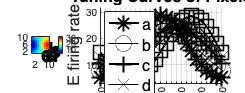

    Fig5D.PaperUnits = 'centimeters';
    Fig5D.PaperSize = [36,28];
    Fig5D.PaperOrientation = "landscape";
    exportgraphics(Fig5D,[FigurePaperPath FigName1 '.pdf'],'Resolution',150)

    close all

Plot Kernel figures: some samples

figure
for SubPlotInd = 1:10
    subplot(2,5,SubPlotInd)
    ShowField_Rec(C_SI_mean(800+SubPlotInd,:)',...
        1:N_HCOutX*NPixX*N_HCOutY*NPixY, N_HCOutX*NPixX, N_HCOutY*NPixY)
    title(sprintf('%d; sum = %.1f',800+SubPlotInd, full(sum(C_SI_mean(800+SubPlotInd,:),'all'))))
    caxis([0 6])
end

LGN/L6 kernels

figure
subplot 151
ShowField_Rec(PixL6Ctgr(:,1),1:3200,N_HCOutX*NPixX,N_HCOutY*NPixY)
subplot 152
ShowField_Rec(PixL6Ctgr(:,2),1:3200,N_HCOutX*NPixX,N_HCOutY*NPixY)
subplot 153
ShowField_Rec(PixL6Ctgr(:,3),1:3200,N_HCOutX*NPixX,N_HCOutY*NPixY)
subplot 154
ShowField_Rec(PixL6Ctgr(:,4),1:3200,N_HCOutX*NPixX,N_HCOutY*NPixY)
subplot 155
ShowField_Rec(PixL6Ctgr(:,5),1:3200,N_HCOutX*NPixX,N_HCOutY*NPixY)